# **Lab 1**

*Joel Sundin, Pablo Gonzalez Baron*

- Histogram Equalization

We start by creating a histogram of the given image. We then calculate the cumulative sum of the histogram and normalizes this array so that it ranges from 0 to 1. Each pixel value and its corresponding equalized value is then mapped and the output is converted back to uint8.

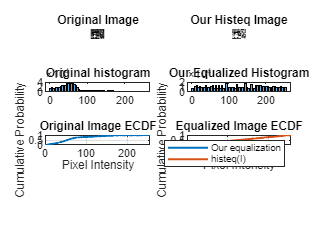

I = imread("images\greytoys.png");
matlab_histeq = histeq(I);
my_histeq = myhisteq(I);
matlab_histeq = histeq(I);


figure
subplot(4, 2, 1)
imshow(I)
title('Original Image')

subplot(4, 2, 2)
imshow(my_histeq)
title('Our Histeq Image')

subplot(4, 2, 3)
histogram(I, 64)
title('Original histogram')

subplot(4, 2, 4)
histogram(my_histeq, 64)
title('Our Equalized Histogram')

subplot(4, 2, 5);% Plot ECDF for the matlab image
num_bins = 256;  % Number of bins for intensity levels
plot(0:num_bins-1, myecdf(I, num_bins), 'LineWidth', 1.5);  % Plot ECDF
title('Original Image ECDF');
xlabel('Pixel Intensity');
ylabel('Cumulative Probability');
grid on; 

% Plot ECDF for the equalized image
subplot(4, 2, 6);
num_bins = 256;  % Number of bins for intensity levels
plot(0:num_bins-1, myecdf(my_histeq, num_bins), 'LineWidth', 1.5);  % Plot ECDF
hold on 
plot(0:num_bins-1, myecdf(matlab_histeq, num_bins), 'LineWidth', 1.5);  % Plot ECDF
title('Equalized Image ECDF');
xlabel('Pixel Intensity');
ylabel('Cumulative Probability');
legend('Our equalization','histeq(I)')
grid on;


function histeq = myhisteq(image)
    histogram = myhist(image);
    sum = cumsum(histogram);
    cdf = sum / sum(end);
    levels = 255;

    mapping = round((levels) * cdf);
    out = mapping(double(image) + 1);
    histeq = uint8(out);
end

function values = myecdf(histeq, num_bins)
    hist_values_eq = imhist(histeq, num_bins);  % Histogram of the equalized image
    probability_values_eq = hist_values_eq / numel(histeq);  % Normalize by total number of pixels
    cdf_values_eq = cumsum(probability_values_eq);  % Cumulative sum of the probabilities
    values = cdf_values_eq;
end

function histogram = myhist(image)
    [rows, cols] = size(image);
    histogram = zeros(1, 256); % [0, 255]

    for i=1:1:rows
        for j=1:1:cols
            pixel_intensity = image(i, j);
            histogram(pixel_intensity + 1) = histogram(pixel_intensity + 1) + 1;
        end
    end
end